# 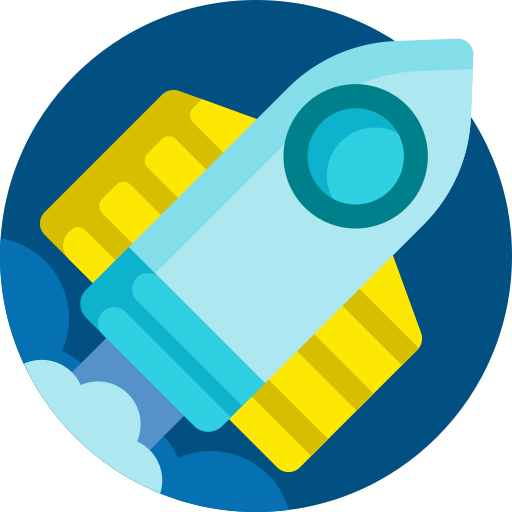

# **MEC3079S: Control Systems**

# Chapter 13 — Digital control systems

## 13.1 Introduction

In the previous chapters we have only considered when signals are continuous, analogue signals. However, modern control engineering often makes use of digital computers to implement feedback controller solutions. This can have many benefits over using analogue controllers, such as:

- reduced cost and engineering effort,

- flexibility in response to design changes, 

- a unified controller and data viewing solution, and

- catering for a single digital computer to serve as controller for multiple subsystems.

Digital computers can take the form of microcontroller, such as an Arduino Uno or Teensy 4, or a real-time enabled computing devices, such as a Rasberry Pi using a specialised operating system. This digital controller is then responsible for, among other things, the computation of the required control action $u(t)$, as a result of the designed feedback controller, $G(s)$. By extension, this device will receive signals (usually in the form of a voltage), convert the voltage to a digital representation (e.g. 16-bit number), perform various mathematical operations corresponding to the desired feedback control structure, and then output a signal that represents the control action.

Based on abovementioned, two important considerations are present in this **Chapter**, namely:

- Digital sampling of analogue signals results in some undesirable gain-phase behaviour, which we need to be aware of accomodate for when designing feedback controllers, and

- When implementing a digital controller, we need to be able to convert continous-time $G(s)$ into a code-based algorithm that can be deployed on physical hardware.

The two points are addressed in detail in the following sections.

### 13.1.1 Digital controller structures

There are commonly two structures in which to incorporate digital controllers within the feedback loop. In the first instance, the digital controller takes the place of the feedback controller in the block diagram, as shown below. 

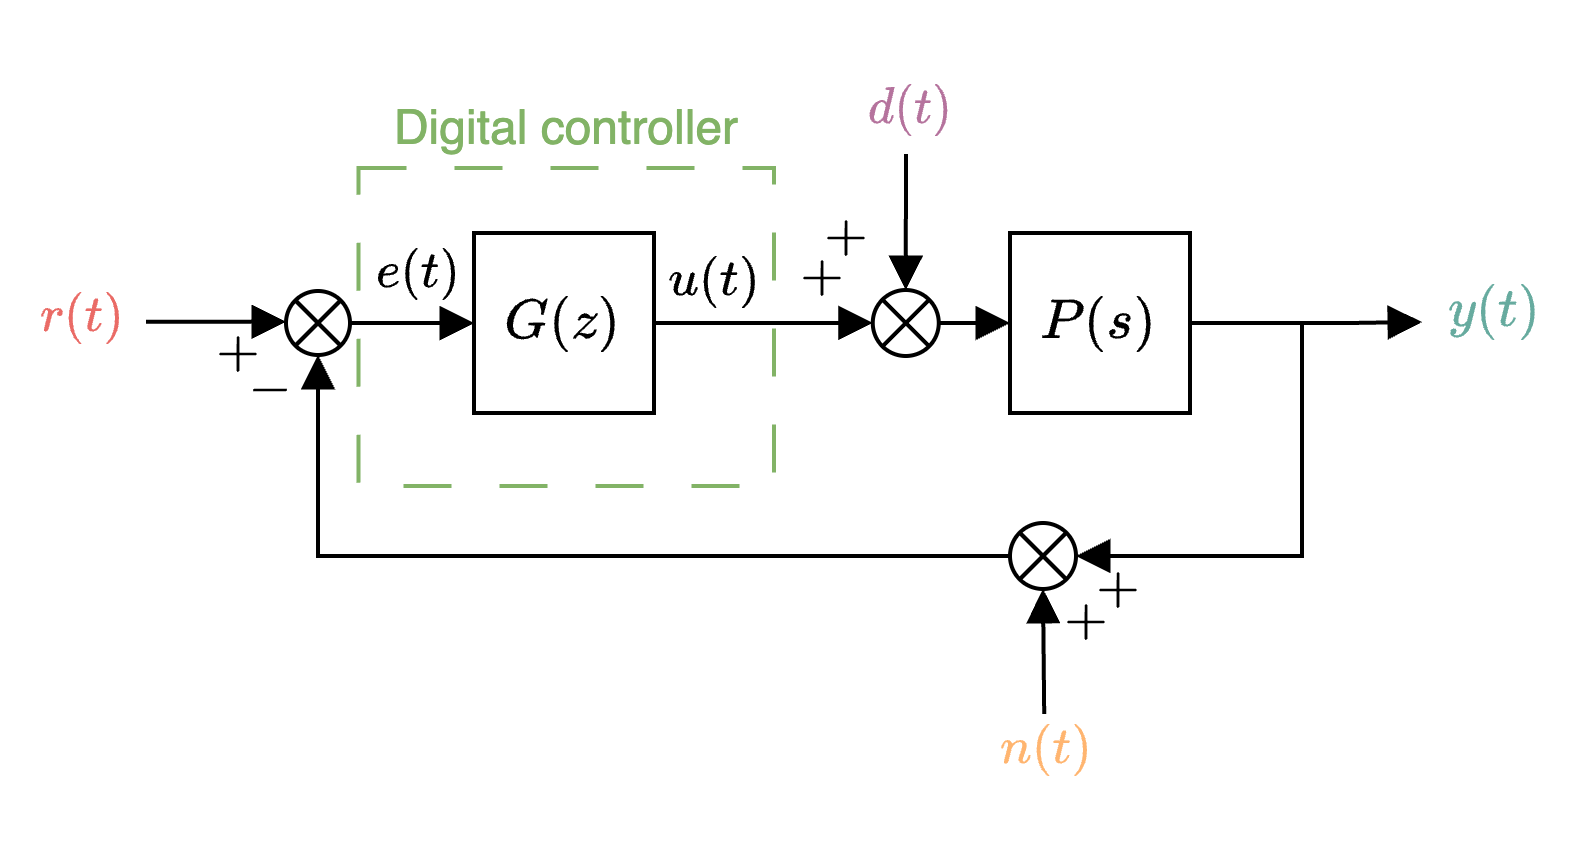

Signals sent to the digital controller (e.g. Arduino) then represent the tracking error, $e(t)$, in the form of a voltage, and signals outputted from the digital controller represent the control action, $u(t)$, which is also usually a voltage. 

In the second instance, as shown below, the digital controller takes the place of the feedback controller, the summing junction, and often also is used to set the reference signal, $r(t)$, in code. 

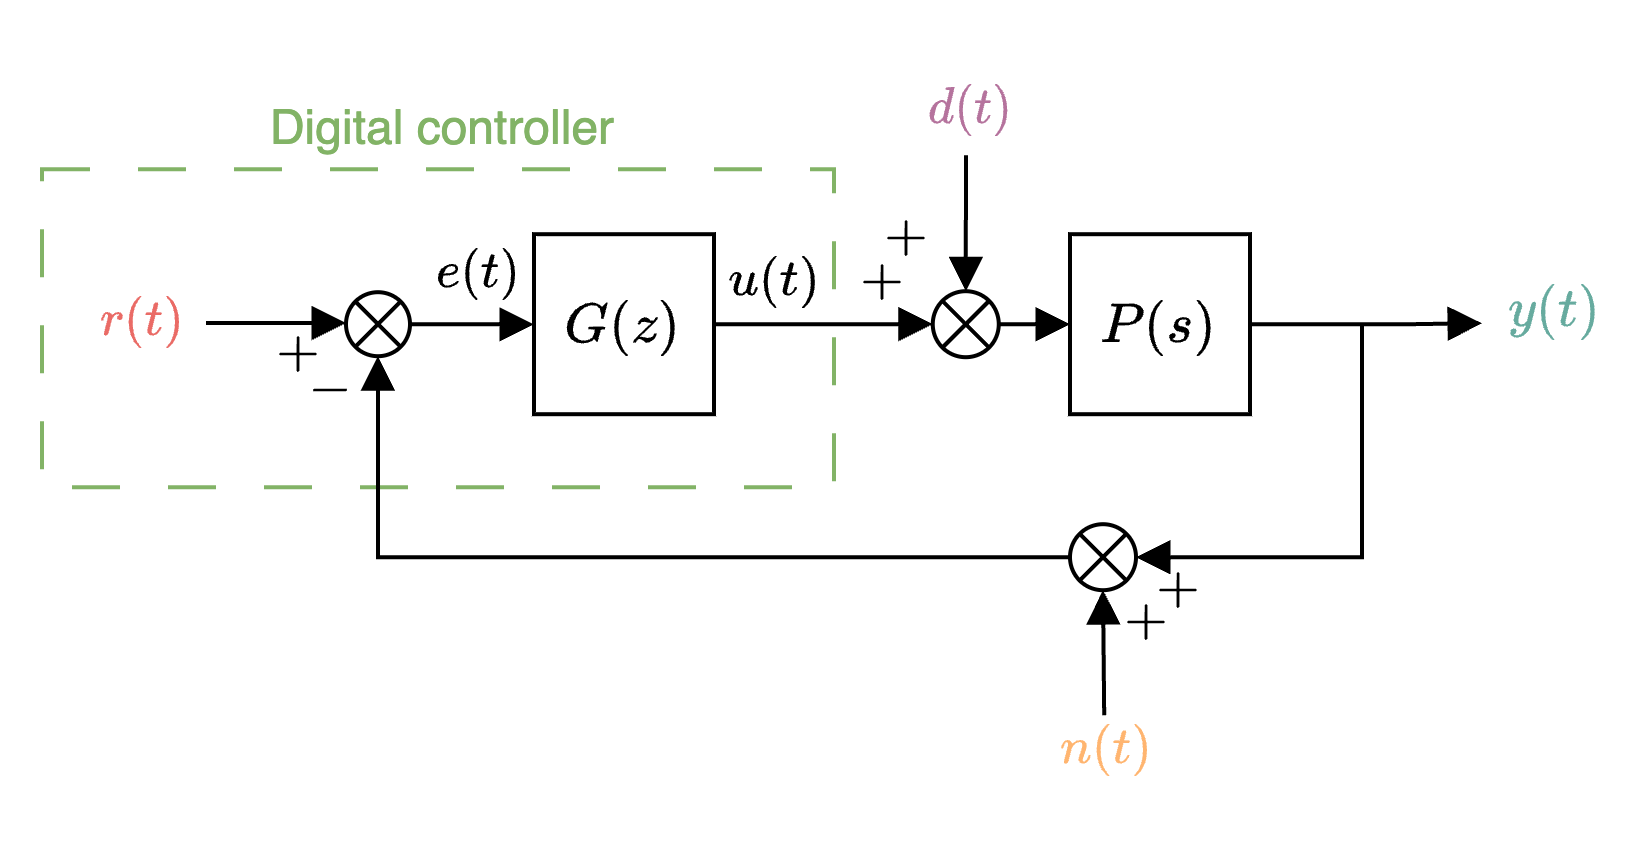

In this form, the measured output is often the only signal that is sent to the digital controller, with the tracking error, $e(t)=r(t)-y(t)$, calculated within the digital controller in code. As with the first instance, the output signal from the controller is still the control action. 

Implicit in the digital controller architecture is the ability to convert continous-time signals into discrete voltages. While not represented in the above figures, the conversion from a continuous to digital signal has some undesirable effects that needs to be modelled and accounted for when doing a robust control design. This is covered in the subsequent sections.

### 13.1.2 Sampling time

Unlike continuous control systems, digital controllers have finite sampling rates, which means that information received by the digital controller is then sampled, usually at fixed intervals of $\Delta T$ seconds, in order to make use of the information in code, as shown below. 

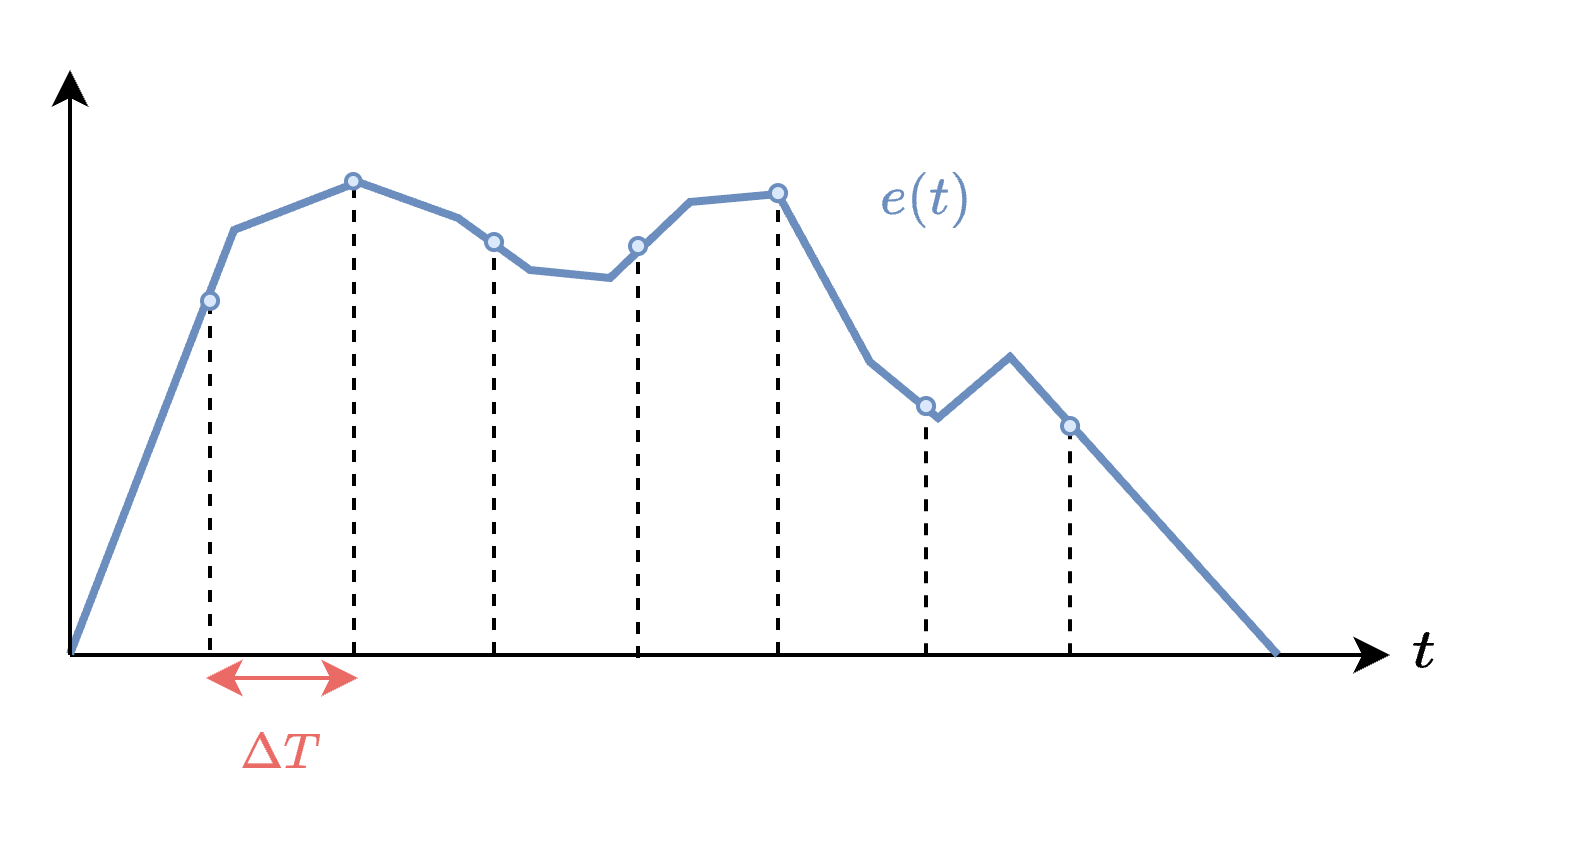

Similarly, signals outputted from the digital controller will also have a fixed and finite output sampling rate. For this course, we will only considers digital controllers with a constant sample time, $\Delta T$, for both input and output sampling.

### 13.1.1 Analogue-to-digital converter 

Control systems that contain both analogue and digital signals must provide a means for conversion from one form to the other, as required by each subsystem. As the name implies, **analogue-to-digital converters (ADCs)** convert analogue signals to their digital counterparts. The process of converting an analogue signal into a digital signal is a two-step process and is not instantaneous. Specifically, there is a delay between the input analogue voltage and the output digital word. For this reason, there are requirements on how quickly a signal must be sampled in order to avoid signal distortion. According to the *Nyquist sampling criterion,* the sampling rate must be at least twice the bandwidth of the signal in order to preserve the fundamental information in the signal.

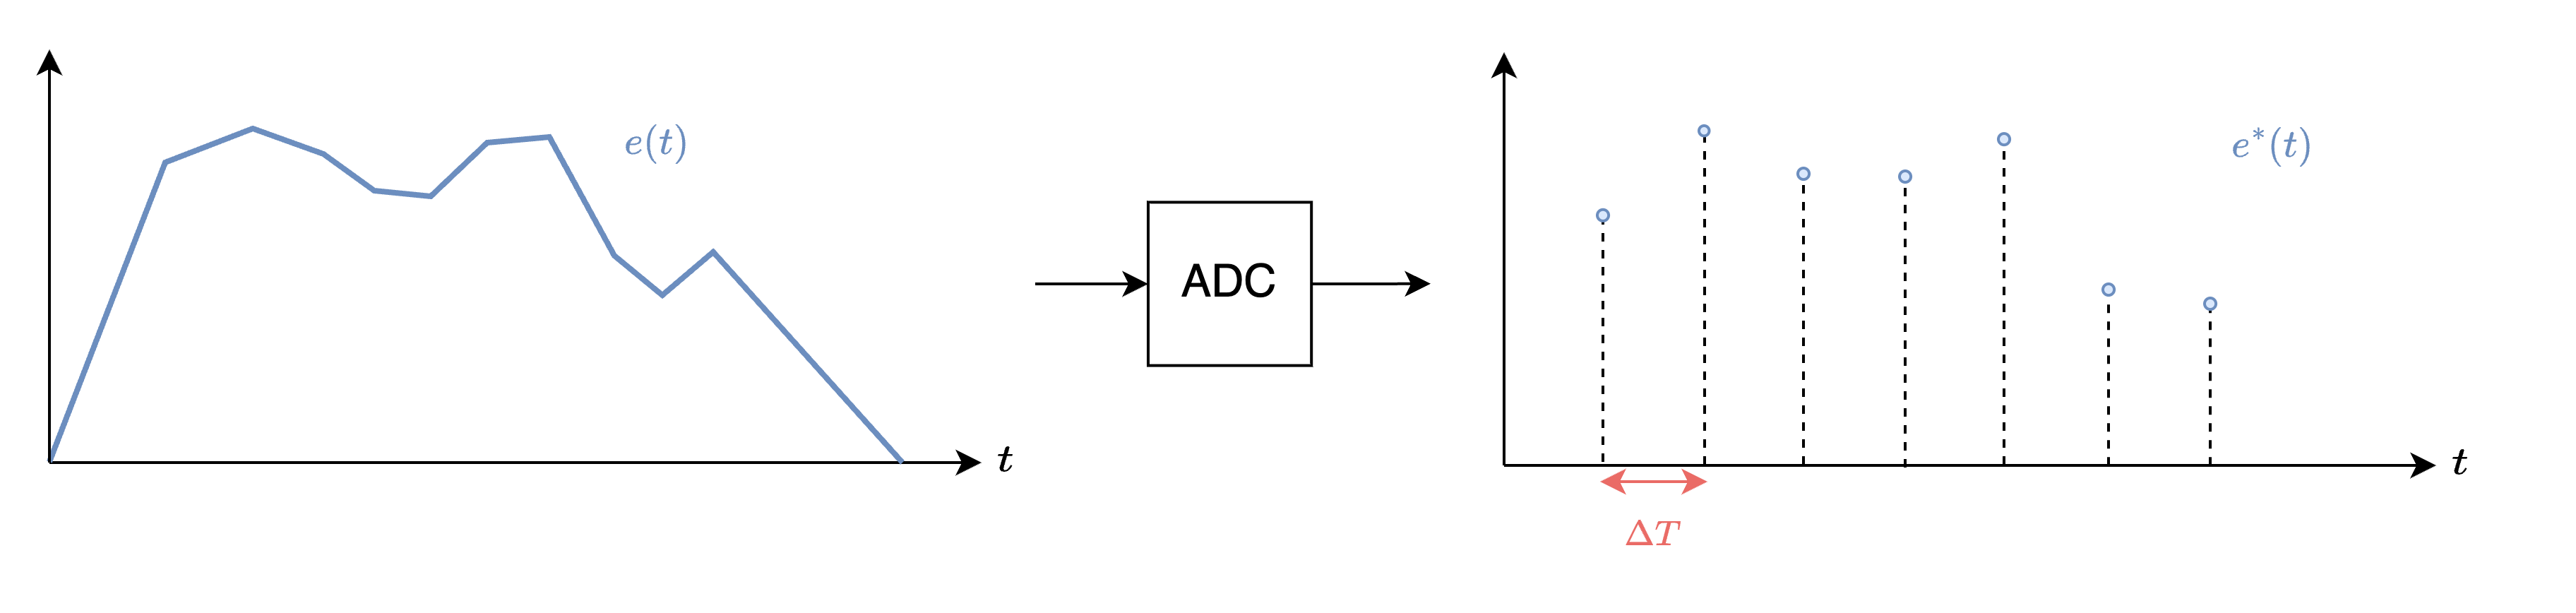

### 13.1.2 Digital-to-analogue converter

**Digital-to-anologue converter (DACs)**, are used to convert digital signals back to the continuous analogue signals. This process is effectively instantaneous, as the relationship between a digital voltage (stored as a binary number) and an analogue voltage is described by a static matrix mapping. Commonly, DACs will hold the current value as a constant between samples. With reference to the figure below, this is representeed by a staircase function of held signals for each sampling instance. We refer to this "staircasing" operation as a *zero-order hold* (ZOH). A first-order hold would represent the intermediate points between two samples using a ramp, and so on.

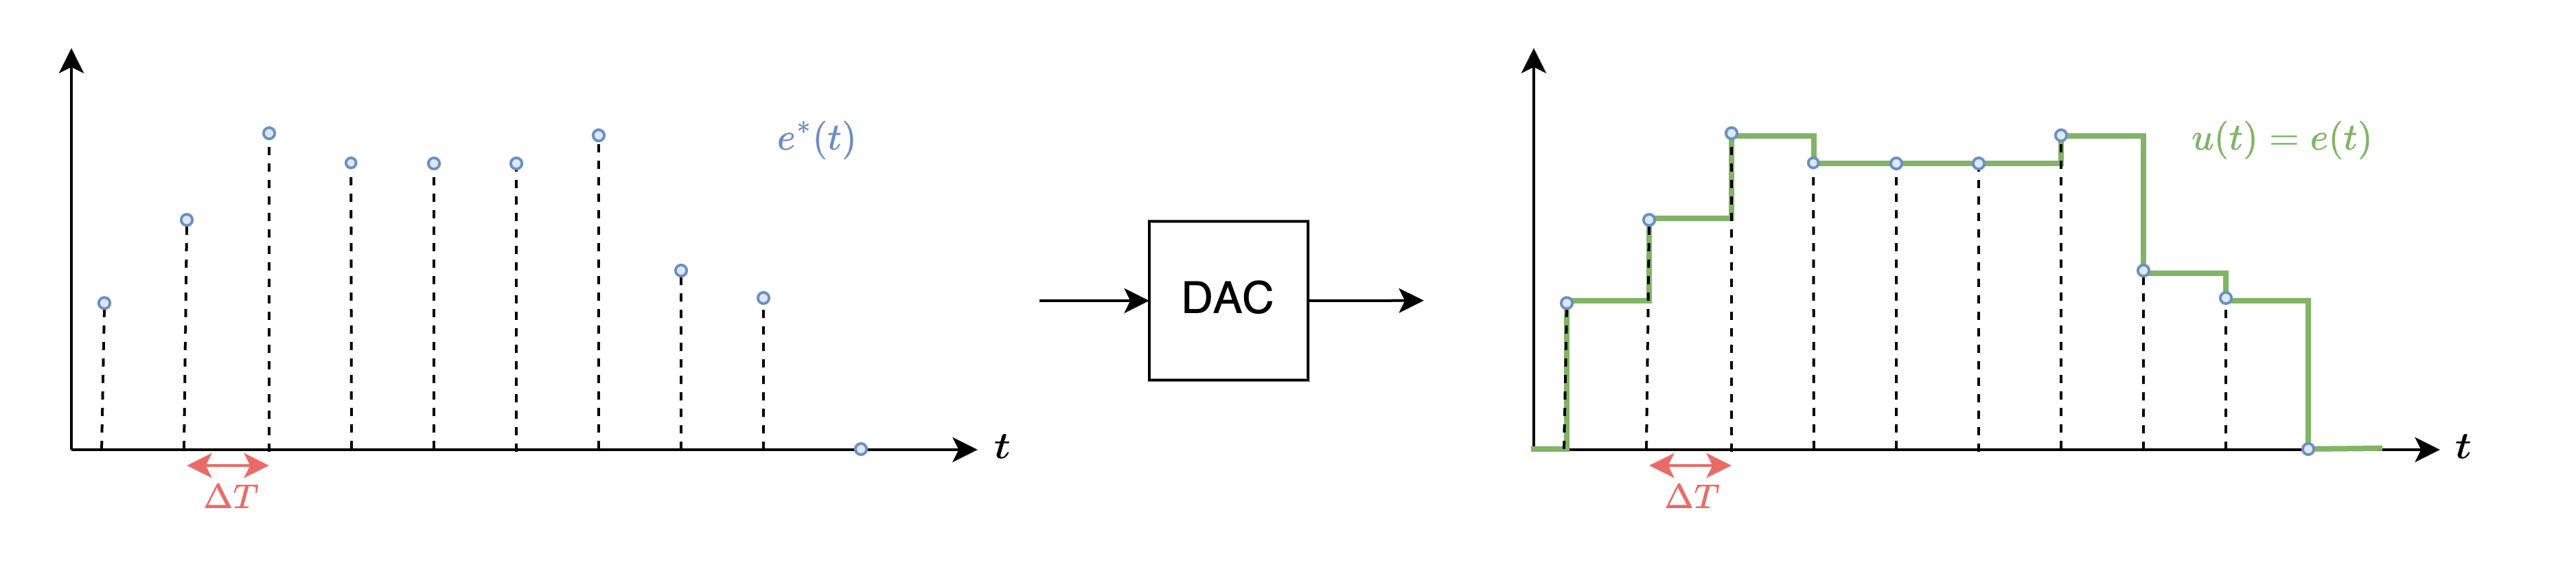

## 13.2 Modelling digital systems

Based on the previous section, it should not be too suprising that the discrete nature of digital systems may alter the performance of a control system when placed in a feedback loop. Specifically, as the sampling time, $\Delta T$, increases, the disparity between the continuous and digital representations of signals increases. This disparity is also worsened when there is nonnegligible quantisation error, but this will not be covered in this course.

As we have honed all our feedback control design tools in the frequency domain, using assumptions about signals in continuous time, it would be beneficial to model or approximate the effects of digital systems in the continuous Laplace domain (and by extension, the continuous frequency domain). If this can be done with sufficient fidelity, we can then proceed with our feedback control design using the same methodology as before.

### 13.2.1 Discrete-time sampled sequences

We have already presented the relationship between continuous time-domain signal, $f(t)$, and the corresponding continuous $s$-domain signal, $F(s)$. If we now consider sampling $f(t)$ at evenly spaced intervals of $\Delta T$, starting at $t=0$ as shown in the figure below, then we can describe the sampled sequence as

$f[n]=\{ f(0),f(\Delta t),f(2\Delta T),...f(\infty \Delta t)\}$,

where $f[k]=f(k\Delta T)$.

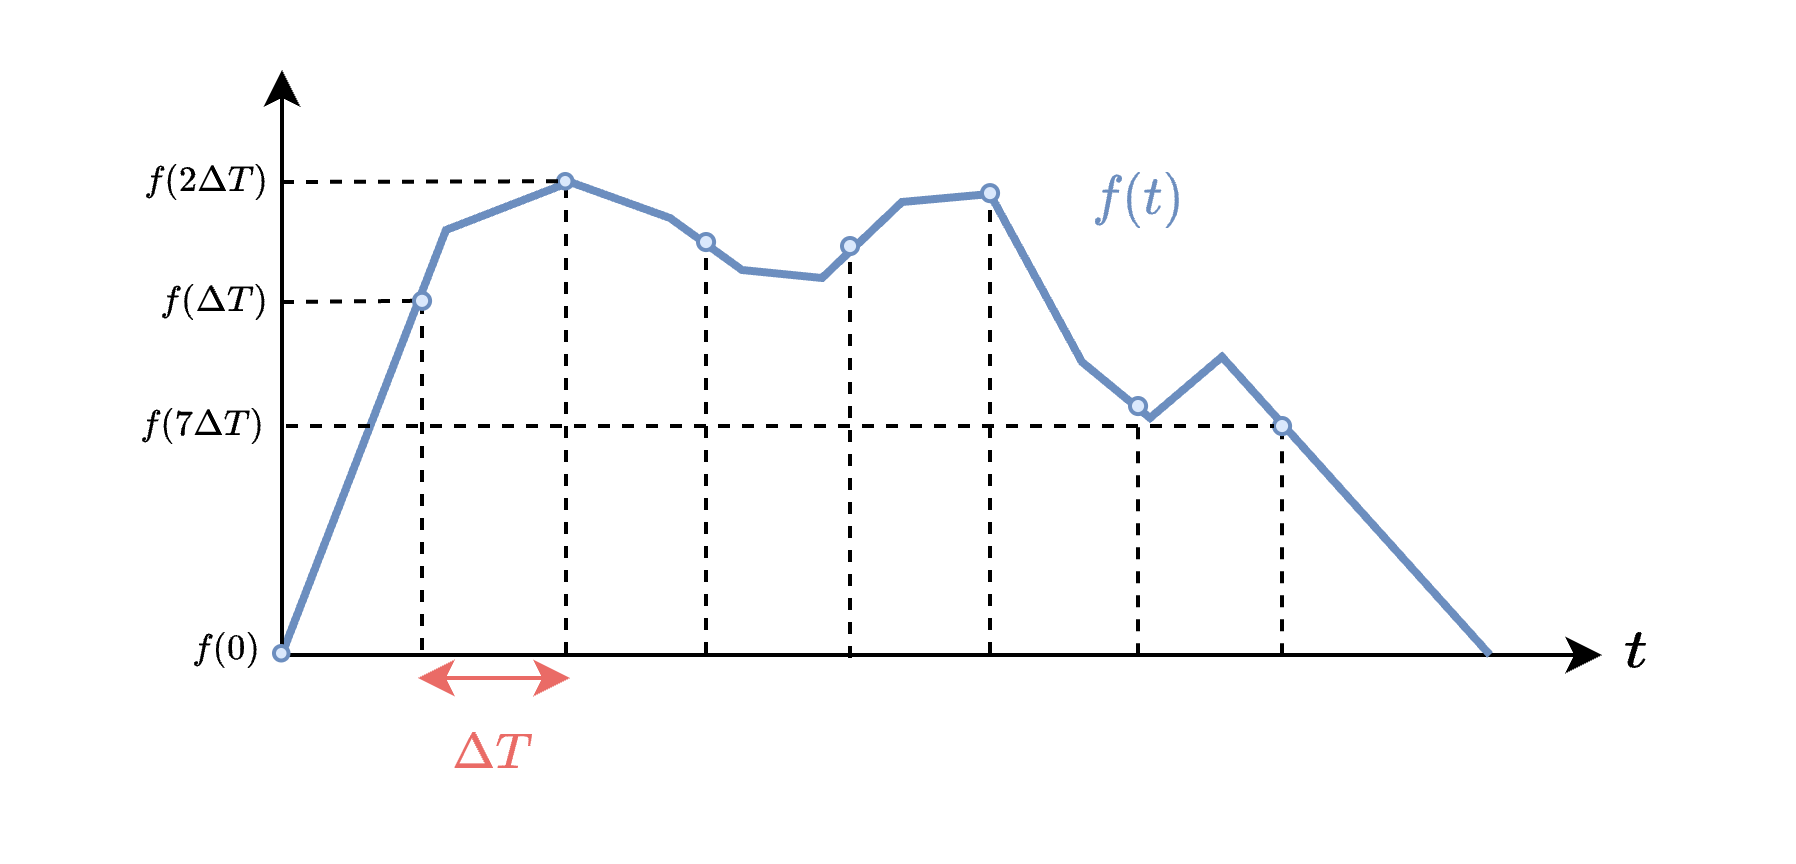

This sampled sequence represents how the digital computer periodically interprets data. Specifically, if a digital computer is sampling the reference, $r(t)$, and measured output signal, $y(t)$, then at sampling instance $k$, these measurements would be interpreted by $r[k]$ and $y[k]$, respectively. As an example, if we were interested in implementing a proportional controller in code, we could calculate the current error (at sample instance $k$) using

$e[k]=r[k]-y[k]$,

and then determine the corresponding control action using

$u[k]=Ke[k]$,

where $K$ is the designed proportional controller.

#### Example

A simple example of a digital proportional controller is shown using the code below for the plant $P(s)=\frac{2}{s}$.

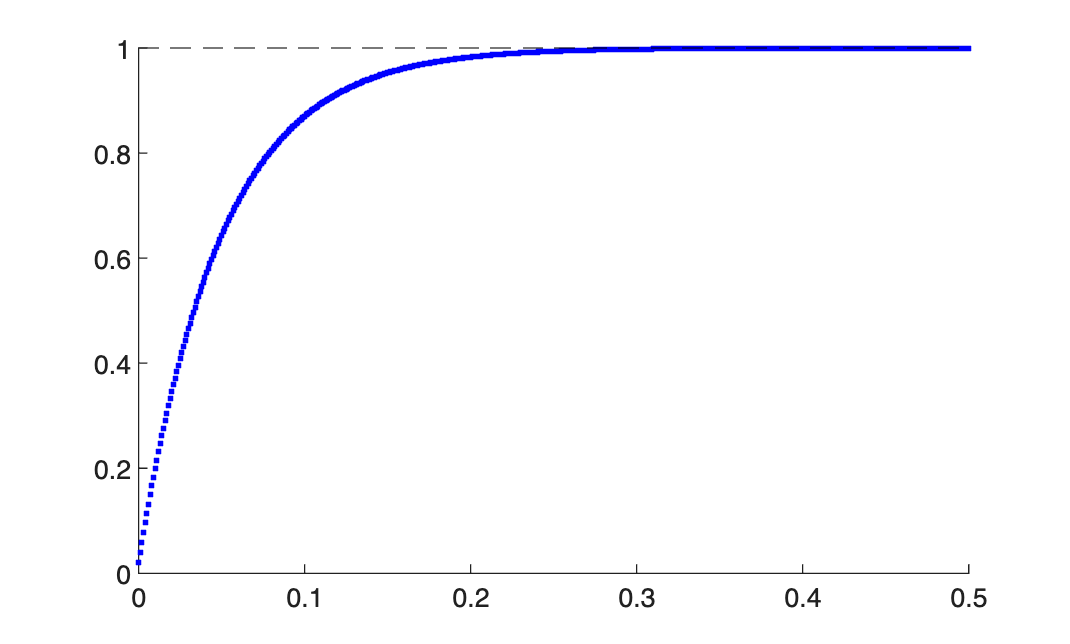

clear
s = tf('s');
P = 2/s;

r = 1; %reference
y = 0; %initial output
K = 10; %proportional gain
dT = 0.001; %sample time

u_past = 0;

figure,hold on
yline(r,'--k','reference')
for t=0:dT:0.5
    e = r-y;    %tracking error at current sample instance
    u = K*e;    %control action at current sample instance

    %plant
    dy = lsim(P,[u u_past].',[0 dT].');
    y = y+dy(2);
    %
    u_past = u;

    %plot
    plot(t,y,'.b')
    pause(dT);
end

### 13.2.2 Approximating digital sampling

While the detail will be spared in this course, it can be shown that a loop transfer function containing a *digital* feedback controller can be approximately modelled by

$L^*(s)=L(s)(1-s\frac{\Delta T}{2})$,

where $L(s)=P(s)G(s)$ is the continuous-time representation of the loop transfer function. In other words, using a digital controller has the approximate effect of adding a right-half s-plane zero at $z=\frac{2}{\Delta T}$. Note that this approximation is only valid when the sampling rate, $f_s=\frac{1}{\Delta T}$, is greater than the highest plant bandwidth frequency that has significant residual. We can visualise the effect that this right-half plane zero has on $L(s)$ for varying sample times using the code below.

clear
s = tf('s');
L = 5/s/(1+s/10)


L =
 
      50
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.


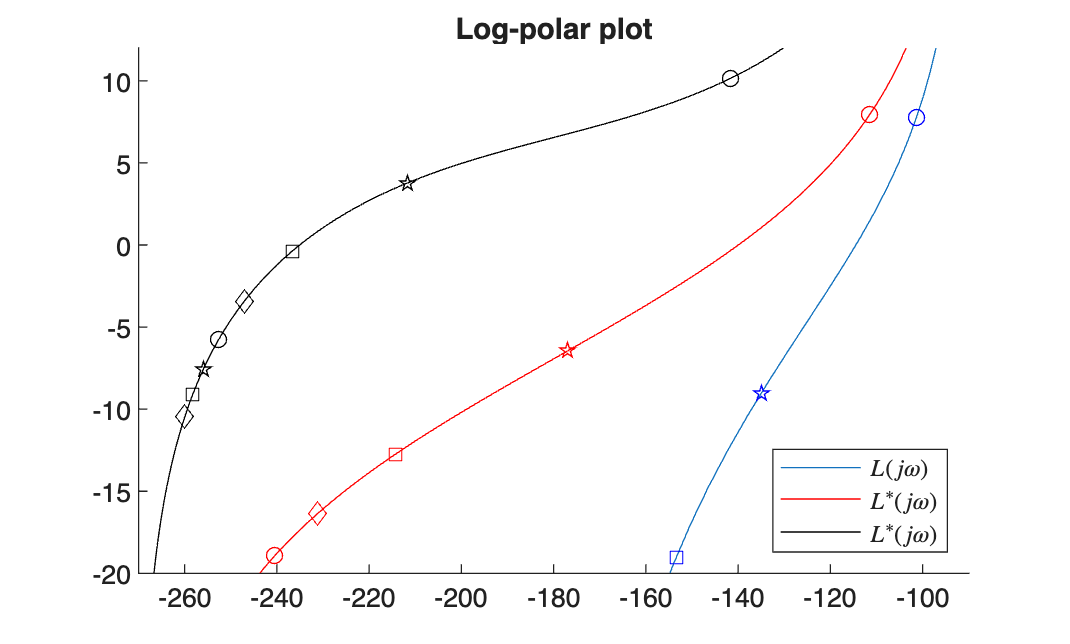

%L = 1/s/(1+s/1)

dT = 0.18;
L_ = L*(1-s*dT/2);


dTT = 0.85;
L__ = L*(1-s*dTT/2);

W = logspace(0.0001,10,1000);

%Lw
Lw_ = squeeze( freqresp(L_,W) );
Lw_angle = angle(Lw_)*180/pi;
for i=1:length(Lw_)
    if( Lw_angle(i) > 0 ), Lw_angle(i)=Lw_angle(i)-360; end
end

Lw__ = squeeze( freqresp(L__,W) );
Lw__angle = angle(Lw__)*180/pi;
for i=1:length(Lw__)
    if( Lw__angle(i) > 0 ), Lw__angle(i)=Lw__angle(i)-360; end
end

[magL,phiL] = nichols(L,{1e-3,1e3});
figure, hold on
plot(squeeze(phiL),squeeze(20*log10(magL)))
plot( Lw_angle, 20*log10( abs(Lw_) ),'r' )
%ylim([-40,12]),xlim([-270,-90])


plot( Lw__angle, 20*log10( abs(Lw__) ),'k' )
ylim([-20,12]),xlim([-270,-90])


icon_array = ['o','p','s','d','o','p','s','d'];
W_ = [2 10 20 30 40 50 60 70];
for i=1:length(W_)
    [mag,phi] = nichols(L,W_(i));
    plot(squeeze(phi),20*log10(squeeze(mag)),'b',Marker=icon_array(i))
    [mag,phi] = nichols(L_,W_(i));
    plot(squeeze(phi)-360,20*log10(squeeze(mag)),'r',Marker=icon_array(i))
        [mag,phi] = nichols(L__,W_(i));
    plot(squeeze(phi)-360,20*log10(squeeze(mag)),'k',Marker=icon_array(i))
end

legend('$L(j\omega)$','$L^*(j\omega)$','$L^*(j\omega)$','','Interpreter','latex','Location','southeast')
title('Log-polar plot')

For $\Delta T=0$, there is no difference between the two frequency responses, as the sample time is instantaneous. However, as $\Delta T$ is increased, we see that the loop transfer function with the digital controller has additional phase lag. Additionally, the right-half plane zero also adds gain. Collectively, the phase lag and gain increase with increasing $\Delta T$, which both also increase in severity as the frequency increases, pushing the $L^*(j\omega)$ locus closer to the critical point. We can also easily show that for sufficiently large $\Delta T$, the $L^*(j\omega)$ locus will intercept the critical point, leading to instability in the feedback loop.

### 13.2.2 Consideration of sample time

Based on the result of the previous section, we need to keep our sample time sufficiently small, relative to the bandwith of $L(j\omega)$. The sampling capabilities of a digital computer will be related to the cost of the device, so if we are financially constrained when choosing a digital controller (when trying to solve a particular control problem), we may have to accept a very limited minimum sample time. In this case, the obtainable performance of the closed-loop system will be fundamentally limited by the sampling rate of the digital device, as at sufficiently high frequencies our loop transfer function will incur too much gain and phase lag to be useful.

In other cases, we will be given specific hardware, with specific sample time constraints. If we know the minimum sample time of our digital device, we can then include this information when evaluating the loop transfer function in the frequency domain. In other words, with $\Delta T$ set as a known value, we can represent $L^*(s)=L(s)(1-s\frac{\Delta T}{2})$ on a log-polar plot once we choose a particular form of $G(s)$. We can then design $G(s)$ as before, with the only difference being that the loop transfer now has the additional right-half plane zero to contend with.

#### Example

*Design a proportional controller for the system, *$P(s)=\frac{10}{s(s+2)$*, which will satisfy the closed-loop second-order specifications of a settling time of 5 seconds, and percentage overshoot of *$25$*%. The proportional controller will be implemented on a digital controller, with a sample time of *$\Delta T=1.5$,* and the resulting sampling effects must be captured in the design.*

Recall that $M_A$, representing the *stay-below *boundary when plotted against a Bode magnitude response, is determined using:

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.35$.

For the *stay-above *boundary, we determine the desired bandwidth frequency using: 

$\zeta=0.71$,

$\omega_n=\frac{4}{\zeta T_s}$, 

$\omega_0=\omega_n\sqrt{ (1-2\zeta^2)+\sqrt{4\zeta^4-4\zeta^2+2}}\approx \omega_n=1.12$ rad/s.

The *stay-above *magnitude bound is then chosen as $M_B=\frac{1}{\sqrt{2}}$, for frequencies $\omega\leq \omega_0$.

Because the feedback controller will be implemented using a digital computer, with a sample time of $\Delta T=1.5$ seconds, the loop transfer function is approximated by


$$L^*(s)=L(s)(1-s\frac{\Delta T}{2})=\frac{10K}{s(s+2)}(1-s\frac{1.5}{2})$$


The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L^*(j\omega)=KP(j\omega)(1-j\omega\frac{1.5}{2})$. Frequency point $\omega=\omega_0$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_0$ to be outside (effectively above) the enclosed green region. 

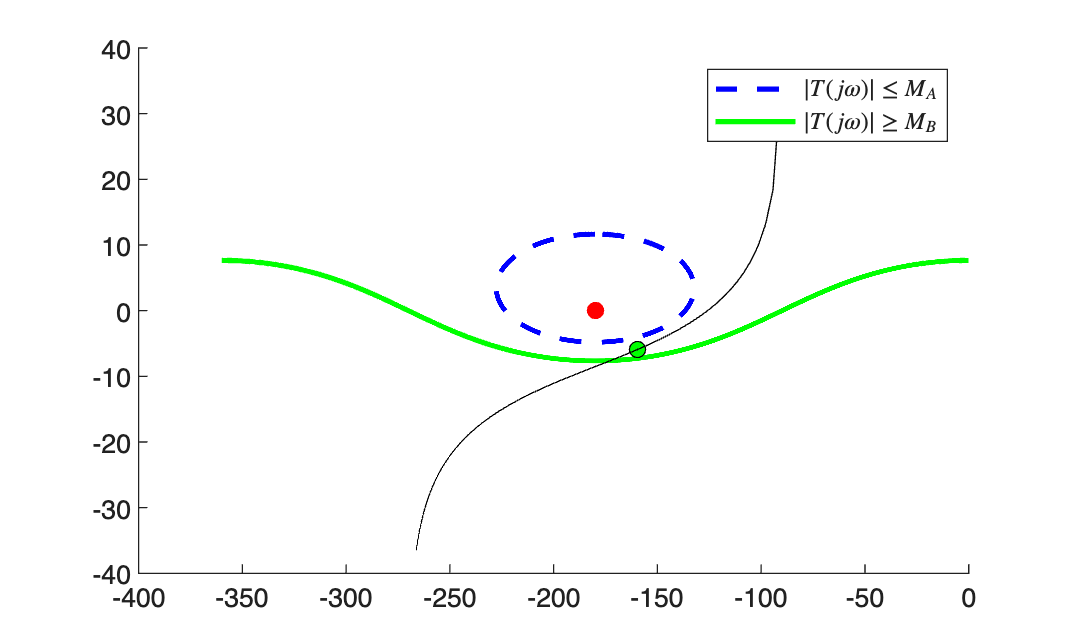

clear
s = tf('s');

P = 10/s/(s+2);
K = 0.1;
dT = 1.5;
L = K*P*(1-s*dT/2);


%specifications
OS = 25;
Ts = 5;

%stay-below bound
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
Ma = 1/( 2*zeta*sqrt(1-zeta^2) );

%stay-above bound
zeta = 0.71;
wn = 4/(zeta*Ts);
w0 = wn*sqrt( (1-2*zeta^2)+sqrt( 4*zeta^4-4*zeta^2+2 ) );
Mb = 1/sqrt(2);

figure, hold on
M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,w0) );

        plot(angle(Lw)*180/pi,20*log10(abs(Lw)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
W = linspace(0.01,50,1e3);
Lw = squeeze( freqresp(L,W) );
Lw_angle = angle(Lw)*180/pi;
for i=1:length(Lw)
    if( Lw_angle(i) > 0 ), Lw_angle(i)=Lw_angle(i)-360; end
end
plot(Lw_angle,20*log10(abs(Lw)),'k');
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')

We were presented with the same example in **Chapter 12**, albeit without the digital sampling, and were able to design a controller of the form $G(s)=K=0.17$ that could meet both specifications. Using this $K$ value now with the digital sample time of $\Delta T=1.5$ seconds is now invalid, as a result of the gain and phase lag increase from the digital hardware. We therefore need to reduce our gain to adhere to the overshoot specification. With a gain of $K\approx0.1$ we can meet both specifications.

## 13.3 The Z-transform

### 13.3.1 Definition

Recall that when sampling a continuous-time signal $f(t)$ at equally spaced intervals of $\Delta T$, we describe the resulting sampled sequence as

$f[n]=\{ f(0),f(\Delta t),f(2\Delta T),...f(\infty \Delta t)\}$,

where $f[k]=f(k\Delta T)$, as shown below.

Analogous to the Laplace transform, we make use of the **Z-transform** to construct a relationship between a discrete sequence of numbers, $f[n]$, and the corresponding $z$-domain signal, $F(z)$. Formally, the z-transform is defined as


$$F(z)=\mathcal{Z}\{ f[n] \} = \sum_{k=0}^\infty f[k] z^{-k}.$$


We can think of the Z-transform as multiplying each value in sequence $f[n]$ by $z^{-k}$, where $k$ is the position of the value in the sequence. For example, the sequence $f[n]=\{0,1,2,2,3,2,1,0\}$ would have the corresponding Z-transform of 


$$\begin{array}{rl}
F(z)
&=\mathcal{Z}\{ f[n] \}, \\
&= 0z^0+1z^{-1}+2z^{-2}+2z^{-3}+3z^{-4}+2z^{-5}+1z^{-6}+0z^{-7}, \\
&= z^{-1}+2z^{-2}+2z^{-3}+3z^{-4}+2z^{-5}+z^{-6}.
\end{array}$$


For stable systems, the *inverse *Z-transform is obtained using


$$f[n] = \mathcal{Z}^{-1}\{ F(z) \} =  \frac{1}{2\pi}\int_{-\pi}^\pi F(e^{j\omega})e^{j\omega n}d\omega.$$


Fortunately, we will make use of transform tables and properties to circumvent using the above equation.

### 13.3.2 Properties of the Z-transform

We will consider sequences with initial conditions equal to zero. This implies that $f[n]=0~\forall n<0$. 

As with the Laplace transform, the Z-transform adheres to **linearity**, which is expressed using


$$\begin{array}{rl}
\mathcal{Z}\{a_1f_1[n]+a_2 f_2[n]\} 
&= \mathcal{Z}\{a_1f_1[n]\}+\mathcal{Z}\{a_2 f_2[n]\},\\
&= a_1\mathcal{Z}\{f_1[n]\}+a_2\mathcal{Z}\{f_2[n]\},\\
&= a_1F_1(z)+a_2F_2(z).
\end{array}$$


The **time delay** property considers taking the Z-transform of a number sequence that has been shifted backwards by $x$ samples, namely $f[n-x]$, with $x>0$ an integer. The Z-transform of $f[n-x]$ is given by


$$\begin{array}{rl}
\mathcal{Z}\{ f[n-x] \} 
&= \sum_{k=0}^\infty f[k-x] z^{-k},\\
&= \sum_{i=-x}^\infty f[i] z^{-(i+x)}, \qquad i=k-x,\\
&= \sum_{i=-x}^\infty f[i] z^{-i}z^{-x},\\
&= z^{-x}\sum_{i=-x}^\infty f[i] z^{-i},\\
&= z^{-x}\sum_{i=0}^\infty f[i] z^{-i}, \qquad f[n]=0,n<0,\\
&= z^{-x}F(z).
\end{array}$$


The inverse relationship is then given by $\begin{array}{rl}
f[n-x] 
&= \mathcal{Z}^{-1}\{z^{-x}F(z)\}.
\end{array}$

The **time advance **property considers taking the Z-transform of a number sequence that has been shifted forwards by one — $f[n+x]$, with $x>0$ an integer. We can make use of the above result for $x<0$ to obtain


$$\begin{array}{rl}
\mathcal{Z}\{ f[n+x] \} 
&= z^{x}F(z).
\end{array}$$


The inverse relationship is then given by $\begin{array}{rl}
f[n+x] 
&= \mathcal{Z}^{-1}\{z^{x}F(z)\}.
\end{array}$

#### Example

*Determine the Z-transform, *$Y(z)$, when $y[n]=au[n]-bu[n-1]$.

We determine the Z-transform using 


$$\begin{array}{rl}
Y(z)&=\mathcal{Z}\{y[n]\},\\
&=\mathcal{Z}\{au[n]-bu[n-1] \},\\
&=a\mathcal{Z}\{u[n]\}-b\mathcal{Z}\{u[n-1] \},\\
&=aU(z)-bz^{-1}U(z),\\
&=\left(a-bz^{-1}\right)U(z).
\end{array}$$


Note that we made use of the *time delay *property in the second last step.

### 13.3.3 Transfer functions

Transfer functions in the $z$-domain can be used to relate the discrete mapping between the input and output of a digital system. This will not be covered in detail in this course, but if we imagine digital sampling at both the input and output of $P(s)$, for example, then the $z$-domain transfer function can be used to relate the discrete input to output mapping. Specifically, if $U(z)$ and $Y(z)$ are known, then the ratio of the Z-transforms describe the discrete transfer function, namely

$P(z)=\frac{Y(z)}{U(z)}$.

#### Example

*Determine the transfer function *$P(z)=\frac{Y(z)}{U(z)}$*, when *$y[n]=au[n]-bu[n-1]$*.*

From the previous example we determined that


$$\begin{array}{rl}
Y(z)&=\left(a-bz^{-1}\right)U(z).
\end{array}$$


$P(z)$ is then simply obtained by dividing through on both sides by $U(z)$, namely

$P(z)=\frac{Y(z)}{U(z)}=a-bz^{-1}$.

## 13.4 Relationship between the Laplace and Z domain.

### 13.4.1 Tustin transform 

Recall that if we are interested in determining the integral of a time-domain signal, expressed as


$$y(t)=\int_{0}^tu(\tau)d\tau,$$


which as a Laplace domain counterpart of $Y(s)=\frac{1}{s}U(s)$, we can numerically approximate the above integral by calculating the approximate area under the signal $u(t)$. This approximate integral, known as the trapezoidal rule, is given in discrete form by

$y[n+1]=y[n]+\frac{\Delta T}{2}\left(u[n+1]+u[n]\right)$, 

as shown in the image below, where $\frac{\Delta T}{2}\left(u[n+1]+u[n]\right)$ represents the approximate area under the signal $u(t)$ between sample $n$ and $n+1$. 

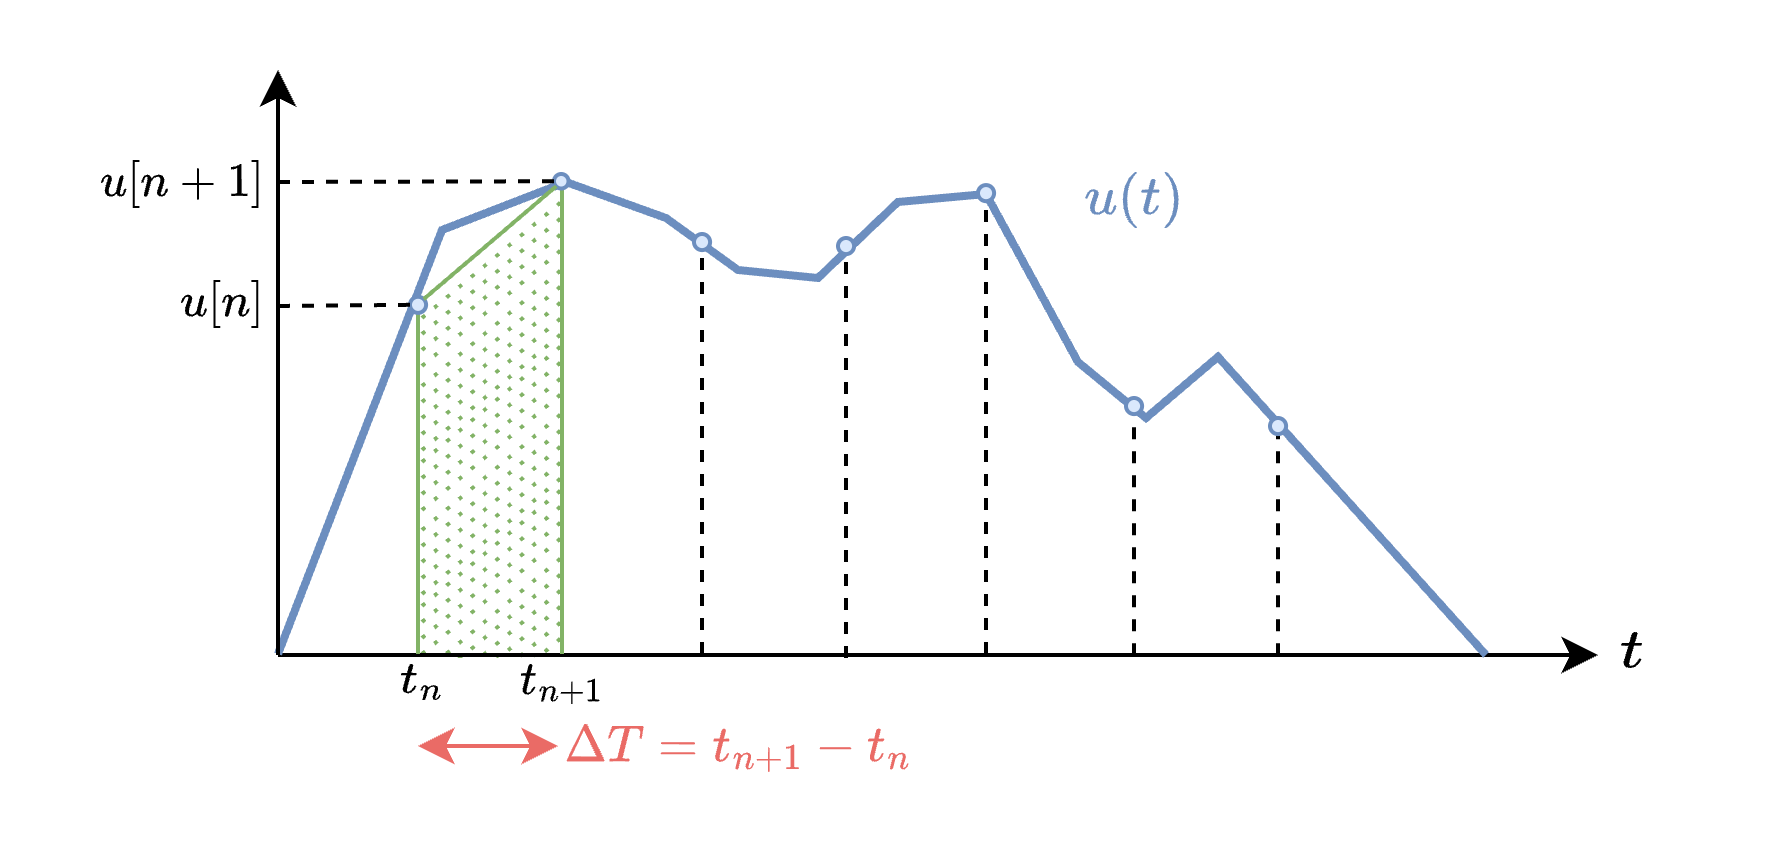

Taking the z-transform of the above equation, which requires making use of our time advance identity, yields

$zY(z)=Y(z)+\frac{\Delta T}{2}\left( zU(z)+U(z)\right)$.

This can then be simplified to express the discrete-time transfer behaviour between $U(z)$ and $Y(z)$ as

$Y(z)=\frac{\Delta T(z+1)}{2(z-1)}U(z)$,

where $P(z)=\frac{\Delta T(z+1)}{2(z-1)}$ represents the approximate integration operation in the $z$-domain. Comparing the equation above with that of $Y(s)=\frac{1}{s}U(s)$, implying that $P(s)=\frac{1}{s}$, suggests that we can approximately relate Laplace domain variable $s$ with the discrete-time variable $z$ using

$s\approx \frac{2(z-1)}{\Delta T(z+1)}$,

or

$z \approx \frac{1+s\Delta T/2}{1-s\Delta T/2}$.

The approximate relationships above collectively describe the **Tustin transform **(also known as the bilinear transform), with the equations representing inverses of eachother. We can use these relationships to approximately map poles in the $s$-domain to the $z$-domain, and vice versa.

We can use the MATLAB command `c2d`, in order to convert a continuous-time transfer function, $G(s)$, into the corresponding discrete-time transfer function, $G(z)$. An example is given in the code block below.

clear
s = tf('s');

G = 10*(1+s*1)/s;

dT = 0.1;
Gz = c2d(G,dT,'Tustin')


Gz =
 
  10.5 z - 9.5
  ------------
     z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.


### 13.4.2 Obtaining discrete-time transfer functions

Now that we have a means of mapping poles from the $s$-domain to the $z$-domain, using $s\approx \frac{2(z-1)}{\Delta T(z+1)}$, we can use this relationship to map continuous-time feedback controllers of the form $G(s)$, to discrete-time representations of $G(z)$. We do this so that we can ultimately convert discrete $G(z)$ into an algorithm that be expressed in code (which is covered in the subsequent section). As per the previous section, we obtain $G(z)$ using

$G(z)=\lim_{s\rightarrow \frac{2(z-1)}{\Delta T(z+1)}} G(s)$.

In other words, we replace $s$ terms with $\frac{2(z-1)}{\Delta T(z+1)}$. Importantly, we must then arrange $G(z)$ to be a ratio of polynomials in $z$, analogous to how $G(s)$ is expressed as a ratio of polynomials in $s$.

#### Example 1

*Determine the discrete-time transfer function *$G(z)$* when *$G(s)=\frac{5}{s+1}$*. Provide your answer as a ratio of polynomials in *$z$*, as a function of *$\Delta T$*.*

Using the formula above, we calculate $G(z)$ using


$$\begin{array}{rl}
G(z)
&=\lim_{s\rightarrow \frac{2(z-1)}{\Delta T(z+1)}} G(s),\\
&=\lim_{s\rightarrow \frac{2(z-1)}{\Delta T(z+1)}} \frac{5}{s+1},\\
&= \frac{5}{\frac{2(z-1)}{\Delta T(z+1)}+1}, \\
&= \frac{5\Delta T(z+1)}{{2(z-1)}+{\Delta T(z+1)}}, \\
&= \frac{5\Delta Tz+5\Delta T}{{(2+\Delta T)z+\Delta T-2}}.
\end{array}$$


#### Example 2

*Determine the discrete-time transfer function *$G(z)$* when *$G(s)=\frac{5}{s+1}$ and $\Delta T=0.1$ seconds*. Provide your answer as a ratio of polynomials in *$z$.

Note that this example is near identical to **Example 1**, albeit with a given sample time. We can therefore use our result from before as


$$\begin{array}{rl}
G(z)
&= \frac{5\Delta Tz+5\Delta T}{{(2+\Delta T)z+\Delta T-2}}.
\end{array}$$


Setting $\Delta T=0.1$ seconds then gives


$$\begin{array}{rl}
G(z)
&= \frac{5\Delta Tz+5\Delta T}{{(2+\Delta T)z+\Delta T-2}},\\
&= \frac{0.5z+0.5}{{2.1z-1.9}}.
\end{array}$$


## 13.5 Implementing a digital controller

### 13.5.1 Discrete-time control structure

The purpose of converting our continuous-time feedback controller, $G(s)$, into a discrete-time representation, $G(z)$, is so that we can subsequently obtain an update equation that determines the required control action for the particular sampling instance. Recall that $G(s)$ effectively maps the tracking error in the Laplace domain, $E(s)$, to the required control action, $U(s)$, based on

$U(s)=G(s)E(s)$.

Analogous to this, if we have obtained $G(z)$ as per the approach in the previous section, then $G(z)$ represents the discrete-time transfer behaviour from $E(z)$ to $U(z)$, namely

$U(z)=G(z)E(z)$.

Our objective is to then use the formulation above to obtain a discrete-time sequence that is made up of $u[n]$ and $e[n]$, as a function of the coefficients in $G(z)$. In general, we can express $G(z)$ as a ratio of polynomials in $z$ using

$\begin{array}{ll}
G(z) &= \frac{a_0+a_1z+a_2z^2 + ...+a_wz^w}{b_0+b_1z+b_2z^2 + ...+b_vz^v}
\end{array}$.

The discrete-time control action is then given by

$U(z)=\frac{a_0+a_1z+a_2z^2 + ...+a_wz^w}{b_0+b_1z+b_2z^2 + ...+b_vz^v}E(z)$.

### 13.5.2 Difference equations

We can repose the above equation by multiplying both sides by the denominator of $G(z)$, which results in

$\left({b_0+b_1z+b_2z^2 + ...+b_vz^v}\right)U(z)=\left({a_0+a_1z+a_2z^2 + ...+a_wz^w}\right)E(z)$.

Expanding both sides, this is equivalent to

${b_0U(z)+b_1zU(z)+b_2z^2U(z) + ...+b_vz^v}U(z)=a_0E(z)+a_1zE(z)+a_2z^2E(z) + ...+a_wz^wE(z)$.

We then rearrange the above equation so that the $U(z)$ term with the highest power is the subject of the equation:

$b_vz^vU(z)=a_0E(z)+a_1zE(z)+a_2z^2E(z) + ...+a_vz^wE(z)+b_0U(z)+b_1zU(z)+b_2z^2U(z) + ...+b_{v-1}z^{v-1}U(z)$.

Finally, dividing through by $b_vz^v$ gives


$$\begin{array}{rl}
U(z)&=\frac{a_0}{b_v}E(z)z^{-v}+\frac{a_1}{b_v}z^{1-v}E(z)+\frac{a_2}{b_v}z^{2-v}E(z) + ...+\frac{a_w}{b_v}z^{w-b}E(z)\\
&\quad+\frac{b_0}{b_v}z^{-v}U(z)+\frac{b_1}{b_w}z^{1-v}U(z)+\frac{b_2}{b_v}z^{2-v}U(z) + ...+\frac{b_{v-1}}{b_v}z^{-1}U(z).
\end{array}$$


Based on our previously defined *time delay* result of $\begin{array}{rl}
f[n-x] 
&= \mathcal{Z}^{-1}\{z^{-x}F(z)\}
\end{array}$, we can now convert the above $z$-domain relationship to a time sequence relationship, which results in the so-called **difference equation** of our control scheme:

$\begin{array}{rl}
u[n]&=\frac{a_0}{b_v}e[n-v]+\frac{a_1}{b_v}e[n-v+1]+\frac{a_2}{b_v}e[n-v+2] + ...+\frac{a_w}{b_v}e[n-v+w]\\
&\quad+\frac{b_0}{b_v}u[n-v]+\frac{b_1}{b_v}u[n-v+1]+\frac{b_2}{b_v}u[n-v+2] + ...+\frac{b_{v-1}}{b_v}u[n-1].
\end{array}$.

Signal $u[n]$ represents the control action at the current sample instance, which is what we are interested in calculating. All other signals are acting at past sampling instances, except for the special case when $w=v$, implying that the term $\frac{a_w}{b_v}e[n-v+w]=\frac{a_w}{b_v}e[n]$ represents the current tracking error after being scaled by $\frac{a_w}{b_v}$. For example, $u[n-1]$ is the control action in the previous sampling instance.

The above equation can then be implemented in code and represents the discrete-time equivalent of our designed $G(s)$. After each iteration of the difference equation above, the information about the signal at the current sampling instance must be passed to the variable holding the signal value at the past instance, which can then be used in the subsquent iteration after $\Delta T$ seconds has passed. This achieved using the following assignments:

Control action:


$$u[n-v]\leftarrow u[n-v+1]$$



$$u[n-v+1]\leftarrow u[n-v+2]$$



$$\vdots$$



$$u[n-1]\leftarrow u[n]$$


Error:


$$e[n-v]\leftarrow e[n-v+1]$$



$$e[n-v+1]\leftarrow e[n-v+2]$$



$$\vdots$$



$$e[n-1]\leftarrow e[n]$$


Note that $e[n]$ is obtained directly from 


$$e[n]=r[n]-y[n],$$


 where $r[n]$ and $y[n]$ are the reference signal and output signal at sample instance $n$, respectively.

#### Example

*Determine the difference equation corresponding to *$G(s)=\frac{5}{s+1}$* as a function of sample time *$\Delta T$.

We previously determined $G(z)$ to be


$$\begin{array}{rl}
G(z)
&= \frac{5\Delta Tz+5\Delta T}{{(2+\Delta T)z+\Delta T-2}}.
\end{array}$$


Based on the result above, we know that 


$$\begin{array}{rl}
U(z)
&=G(z)E(z),\\
&= \frac{5\Delta Tz+5\Delta T}{{(2+\Delta T)z+\Delta T-2}}E(z).
\end{array}$$


Multiplying out the denominator of $G(z)$ gives

$(2+\Delta T)zU(z)+(\Delta T-2)U(z)=5\Delta TzE(z)+5\Delta TE(z)$.

We then rearrange for the highest power of $U(z)$, which gives us

$(2+\Delta T)zU(z)=5\Delta TzE(z)+5\Delta TE(z)-(\Delta T-2)U(z)$.

Next, we divide through by the coefficient of $U(z)$ on the left-hand side:

$U(z)=\frac{5\Delta T}{2+\Delta T}E(z)+\frac{5\Delta T}{2+\Delta T}z^{-1}E(z)-\frac{\Delta T-2}{2+\Delta T}z^{-1}U(z)$.

Finally, we use the *time delay *property of the Z-transform to determine the difference equation as

$u[n]=\frac{5\Delta T}{2+\Delta T}e[n]+\frac{5\Delta T}{2+\Delta T}e[n-1]-\frac{\Delta T-2}{2+\Delta T}u[n-1]$.

An example of implementing this difference equation in MATLAB is shown below (for interest sake) for the plant $P(s)=\frac{0.5}{s}$ and varying $\Delta T$ values.

clear
s = tf('s');
P = 0.5/s; %plant

r = 1; %reference
y = 0; %initial output
dT = 0.3; %sample time

e_past = 0;
u_past = 0;

y_ = [];

figure,hold on
yline(r,'--k','r(t)')
for t=0:dT:10
    e = r-y;    %tracking error at current sample instance
    u = 5*dT/(2+dT)*e+5*dT/(2+dT)*e_past-(dT-2)/(2+dT)*u_past;    %control action at current sample instance

    %plant
    dy = lsim(P,[u u_past].',[0 dT].');
    y = y+dy(2);
    %
    
    %update states
    u_past = u; %set past control action equal to current control action for next iteration
    e_past = e; %set past error equal to current error for next iteration

    y_ = [y_ y];
end
plot(0:dT:10,y_,'-r')

We can verify that our discrete-time implementation matches that of our continuous-time system by overlaying the step response generate from the code above with a simulated continuous-time step response, using the code below. 

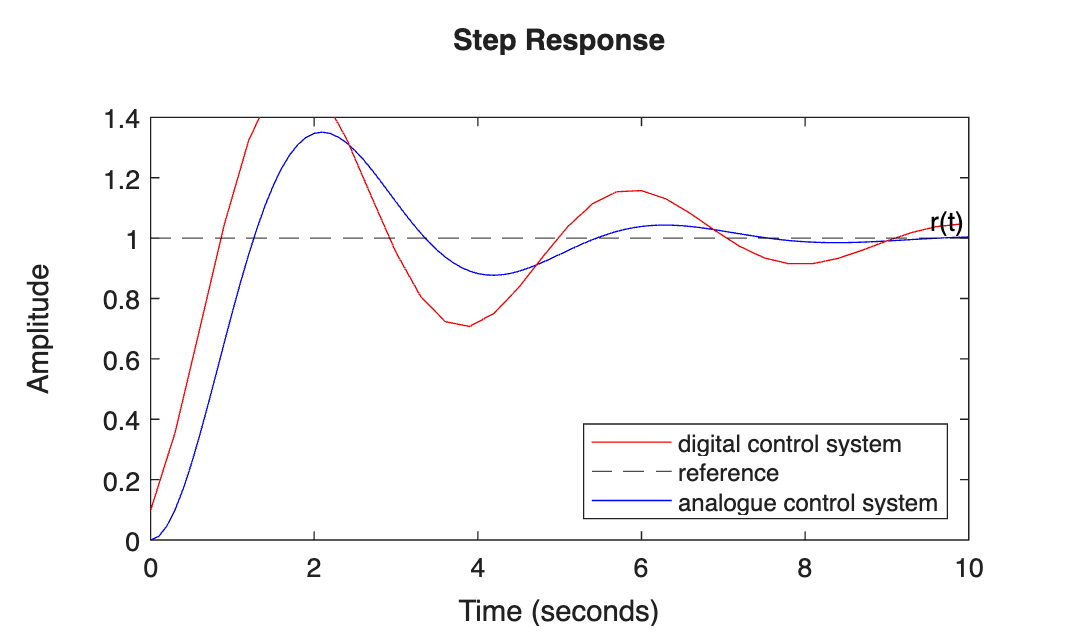

G = 5/(s+1);
T = P*G/(1+P*G);
step(T,10,'b')

legend('digital control system','reference','analogue control system',Location='southeast')

Notably, for sufficiently small $\Delta T$, the two responses are identical, but as the sample time is increased, we see larger disparities between the two. The digital closed-loop system is also shown to become more oscillatory than the continous-time equivalent, as a result of the increased gain and phase lag from the digital sampling.

### 13.5.3 Digital controller synthesis

The following code can be used to automatically convert a controller $G(s)$, defined in the Laplace domain, to the corresponding difference equation.

#### Initialisation

#### Every iteration

#### Example

*Determine the difference equation for the PI controller given by *$G(s)=10\frac{1+5s}{5s}$ when the sampling time is $T_s=0.001$.

Using the initialisation script above, we obtain:

s = tf('s');
G = 10*(1+5*s)/(5*s);
Ts = 1e-3;
Gz = c2d(G,Ts,'tustin') %Tustin transform applied to G


Gz =
 
  10 z - 9.999
  ------------
     z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.


[a, b] = tfdata(Gz, 'v') % Extract coefficients

a =    10.0010   -9.9990


b =      1    -1


b = b/b(1)

b =      1    -1


a = a/b(1)

a =    10.0010   -9.9990



e_ = zeros(length(a)-1,1);
u_ = zeros(length(b)-1,1);

The difference equation describing the discrete feedback controller implementation follows as


$$\begin{array}{rl}
u[n]&=&-b_2u[n-1]+a_1e[n]+a_2e[n-1],\\
&=&u[n-1]+10.01e[n]-9.999e[n-1].
\end{array}$$


This difference equation can be implemented on embedded hardware to execute the PI controller.